# Tutorial example: 3D function

In this second example, we apply PCE-GPR to a simple illustrative 3D function, i.e.,


$$y=\mathcal{M}(x_1,x_2,x_3)=e^{-10/x_1}(2\cos(x_2)+\sin(x_3))$$


We consider the following distributions for the input parameters:

- 
$$x_1\sim\mathcal{U}(1,9)$$


- 
$$x_2\sim\mathcal{N}(5,1)$$


- 
$$x_3\sim\mathcal{N}(3,2)$$


## Initialization

Cleaning and definition of plot parameters

% cleaning
clear all
clc
close all

% plot parameters
BLUE = [0 0.4470 0.7410];
RED = [0.8500 0.3250 0.0980];
YELLOW = [0.9290 0.6940 0.1250];
GREEN = [0.4660,0.6740,0.1880];
GRAY = [0.6,0.6,0.6];
PURPLE = [0.4940, 0.1840, 0.5560];
CYAN = [0.3010, 0.7450, 0.9330];

Define simulation parameters. You are allowed to:

- change the number of training samples `Ntrain` (affects the overall accuracy of the PCE-GPR model)

- change the PCE order `p` (affects the accuracy of the approximate PCE model vs the GPR model and the associated statistics)

- change the standard deviation of noise on the training observations (`sigma_n`)

- choose the hyperparameter estimation method: maximum likelihood (ML; toolbox default) or cross-validation (CV)

- chose between interpolation or regression mode (neglects or considers noise on the training observations)

- chose between isotropic (same $\rho$ for all inputs) or anisotropic kernel (different $\rho$ for each input)

- change the number of posterior sample trajectories `Ntraj` (affects the accuracy of numerical calcultions of posterior distributions)

% simulation parameters
d = 3; % number of random input parameters
Ntrain =110; % number of training samples
p =16; % maximum PCE order
sigma_n =0; % noise standard deviation
EstimationMethod = 'ML'; % hyperparameter estimation method
IsotropicKernel = false; % kernel type
Noise = false; % interpolation or regression mode
Ntraj = 10000; % number of posterior trajectories (for numerical calculations)
Nmc = 1e4; % number of test Monte Carlo samples (for error estimates)
nugget = 1e-10; % regularization term for posterior covariances

rng(1); % for reproducibility

% define target function
fun = @(x) exp(-10./x(:,1)).*(2*cos(x(:,2))+sin(x(:,3)));

% define input distribution
Xdist(1) = makedist("Uniform","lower",1,"upper",9);
Xdist(2) = makedist("Normal","mu",5,"sigma",1);
Xdist(3) = makedist("Normal","mu",3,"sigma",2);


## Reference Monte Carlo samples

First of all, we draw test samples according to the input distribution and we use them to compute reference values for the mean $\mu_y$ and variance $\sigma_y^2$ of the output $y$.

% Monte Carlo
x_lhs = lhsdesign(Nmc,d);
x_mc(:,1) = Xdist(1).icdf(x_lhs(:,1));
x_mc(:,2) = Xdist(2).icdf(x_lhs(:,2));
x_mc(:,3) = Xdist(3).icdf(x_lhs(:,3));
y_mc = fun(x_mc);

% reference mean and variance
mean_mc = mean(y_mc);
var_mc = var(y_mc);

## Training samples

Next, we compute training samples by drawing them randomly from the input distribution using Latin hypercube sampling (LHS).

% training samples
x_lhs = lhsdesign(Ntrain,d);
x_train(:,1) = Xdist(1).icdf(x_lhs(:,1));
x_train(:,2) = Xdist(2).icdf(x_lhs(:,2));
x_train(:,3) = Xdist(3).icdf(x_lhs(:,3));
y_train = fun(x_train);

## Training the PCE-GPR model

We now train our PCE-GPR model with the specified settings. Before calling the training function, we need to define the structure describing the input distribution.

% define distribution structure
distr(1).Type = 'unif';
distr(1).Parameters = [Xdist(1).Lower,Xdist(1).Upper];
distr(2).Type = 'norm';
distr(2).Parameters = [Xdist(2).mu,Xdist(2).sigma];
distr(3).Type = 'norm';
distr(3).Parameters = [Xdist(3).mu,Xdist(3).sigma];

% train PCE-GPR model
M_pce_gpr = train_pce_gpr(x_train,y_train,distr,'EstimationMethod',EstimationMethod,'IsotropicKernel',IsotropicKernel,'Noise',Noise);

Copyright 2013-2022, Stefano Marelli and Bruno Sudret, all rights reserved.
This is UQLab, version 2.0
UQLab is distributed under the BSD 3-clause open source license available at: 
C:\EMC Group\tools\UQLab_Rel2.0.0\LICENSE.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information

---   Calculating the Kriging metamodel...                              ---

                          Median        Current pop   Stall
Generation   f-count      f(x)          best f(x)     

## Evaluating the GPR model

We can now use the PCE-GPR model to make predictions of the Monte Carlo samples. Since we are in 3D scenario, we can assess the prediction accuracy by computing the scatter plot between the reference Monte Carlo values and the model predictions.

% PCE-GPR prediction
[y_pred_gpr,~] = predict_pce_gpr(M_pce_gpr,x_mc);

% plot
figure(1)
scatter(y_mc,y_pred_gpr,'MarkerEdgeColor',GREEN,'DisplayName','GPR model'); hold on;
xlabel('Reference');
ylabel('Prediction');
title('Scatter plot');

## Polynomial chaos expansion model

As we have seen, the GPR part of the PCE-GPR model allows us to calculate predictions. However, we may want to convert this model into an approximate PCE with the predefined order `p`, from which statistical moments and sensitivity indices are computed analytically. To this end, we need to

- Compute the set of multi-indices using the function `PCEindex`

- Use the method `get_pce_gpr_coeff `to obtain the corresponding PCE coefficients.

The PCE coefficients are computed probabilistically in terms of an expected value and an associated covariance matrix. The method returns an updated model structure with the expected value of the PCE coefficients (field `.pce_coeff`) and their covariance matrix (field `.cov_pce_coeff`). The expected value is computed as


$$\mathbf{\mu}_{\mathbf{c}}=\mathbf{\Lambda}\mathbf{\Psi}\mathbf{\alpha}$$


where $\mathbf{\Psi}$ is a $N_\mathrm{train}\times K$ matrix with all the basis functions evaluated at the training points ($\Psi_{kl}=\psi_k(x_l)$)  and $\mathbf{\Lambda}$ is a diagonal matrix with normalization factors that depend on the kernel and hence on the input distribution. The covariance matrix of the PCE coefficients is computed as


$$\mathbf{\Sigma}_{\mathbf{c}}=\sigma_\mathrm{tot}^2(1-\tau)\left(\mathbf{\Lambda}-(1-\tau)\mathbf{\Lambda}\mathbf{\Psi}\tilde{\mathbf{R}}^{-1}\mathbf{\Psi}^T\mathbf{\Lambda}\right)$$


% define multi-index set
kvec = PCEindex(p,d);

% retrieve PCE coefficients and add it to model structure
M_pce_gpr = get_pce_gpr_coeff(M_pce_gpr,kvec);

Now, we are able to evaluate the PCE model! The PCE model is defined as


$$y=\sum_{k=1}^Kc_k\psi_k(x)$$


where $\psi_k$ are the polynomial chaos basis functions (in this case, Legendre polynomials given the uniform input distribution).

It should be noted that PCE-GPR defines a probabilistic model for the PCE coefficients. The coefficient vector $\mathbf{c}$ is a multivariate Gaussian random variable whose mean vector $\mathbf{\mu}_\mathbf{c}$ and covariance matrix $\mathbf{\Sigma}_\mathbf{c}$.

An handle to the basis functions is available in the model structure (field `.basisfun`). The basis functions can be evaluated using the auxiliary function `evalBasis_heterogeneous`, which returns a $N_\mathrm{val}\times K$ matrix $\mathbf{\Psi}^*$ with all the basis functions evaluated at the given evaluation points (we use the superscript * to distinguish it from the matrix $\mathbf{\Psi}$ evaluated at the training samples). Hence, the vector of predictions is obtained as


$$\mathbf{y}=\mathbf{\Psi}^*\mathbf{c}$$


Given the linearity of the PCE model, the *average* predictions are obtained by using the mean vector of PCE coefficients as $\mathbf{c}$.

Note that the PCE model is a finite projection, onto the basis functions indicated by `kvec`, of the GPR kernel model. Increase the order `p` to make the two models match as much as possible!

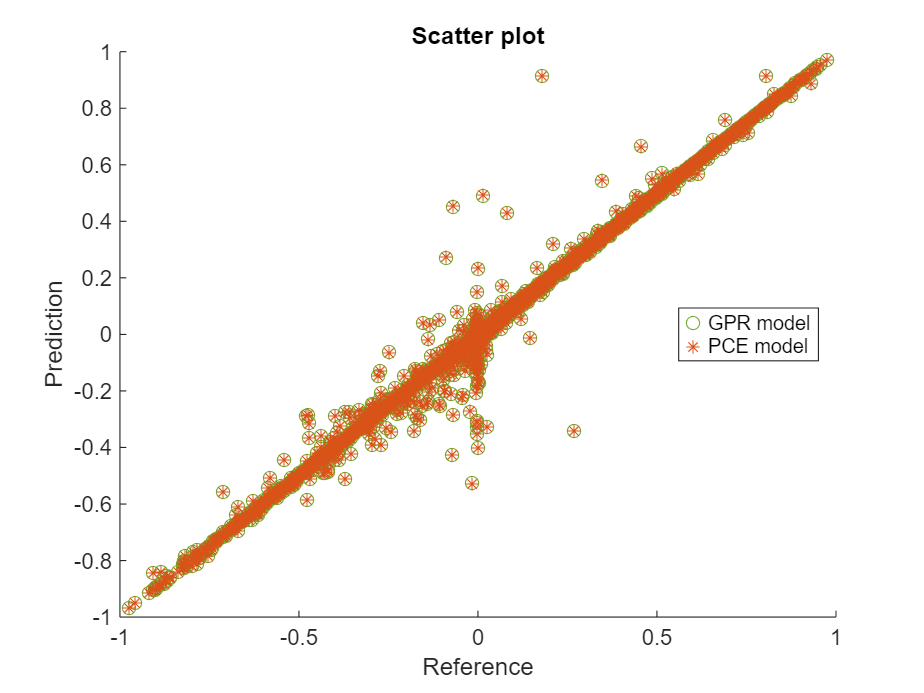

% evaluate PCE model
[~,y_pred_pce] = predict_pce_gpr(M_pce_gpr,x_mc);

% plot
figure(1)
scatter(y_mc,y_pred_pce,'*','MarkerEdgeColor',RED,'DisplayName','PCE model');

legend('Location','east');

## Statistics

The PCE model readily allows computing the mean value $\mu_y$ and the variance $\sigma_y^2$ of $y$ as


$$\mu_y=c_1$$


and


$$\sigma_y^2=\sum_{k=2}^Kc_k^2$$


respectively. Since the PCE-GPR model provides PCE coefficients as random variables, we can evaluate the above two moments probabilistically. The method `get_pce_gpr_stats` carries out the calculation analytically. However, let us first proceed numerically, as follows:

- We generate a large number (`Ntraj`) of posterior samples ("trajectories") of the PCE coefficients

- We evaluate the corresponding samples of $\mu_y$ and $\sigma_y^2$

- From the samples of $\mu_y$ and $\sigma_y^2$, which we compute their expectation, variance, and distribution.

% number of coefficients
K = size(kvec,1);

% draw random PCE coefficients
pce_post = M_pce_gpr.pce_coeff + sqrtm(M_pce_gpr.cov_pce_coeff+nugget*eye(K))*randn(K,Ntraj);

% mean (= first PCE coefficient)
mu_y = pce_post(1,:);

% expectation and variance of the mean (numerical)
mean_mu_y_num = mean(mu_y);
var_mu_y_num = var(mu_y);

% distribution of the mean (numerical)
[pdf_mu_y_num,xi_mu_y] = ksdensity(mu_y);

% variance (= sum of squared PCE coefficients except the first)
sig2_y = sum(pce_post(2:end,:).^2);

% expectation and variance of the variance (numerical)
mean_sig2_y_num = mean(sig2_y);
var_sig2_y_num = var(sig2_y);

% distribution of the variance (numerical)
[pdf_sig2_y_num,xi_sig2_y] = ksdensity(sig2_y);

% plots
figure(2)
subplot(1,2,1)
plot(xi_mu_y,pdf_mu_y_num,'-','Color',BLUE,'LineWidth',1,'DisplayName','numerical'); hold on;
xlabel('$\mu_y$','interpreter','latex');
title('Posterior pdf of \mu_y');

subplot(1,2,2)
plot(xi_sig2_y,pdf_sig2_y_num,'-','Color',BLUE,'LineWidth',1,'DisplayName','numerical'); hold on;
xlabel('$\sigma_y^2$','interpreter','latex');
title('Posterior pdf of \sigma_y^2');

legend('Location','northeast');

We now compare the obtained results with the analytical predictions from the PCE-GPR method.

% retrieve statistics from PCE-GPR model
[mu_y,sig2_y,St_y,var_mu_y,var_sig2_y,var_St_y,pdf_mu_y,pdf_sig2_y,pdf_St_y] = get_pce_gpr_stats(M_pce_gpr);

% compare Monte Carlo estimate of output variance vs confidence interval of
% PCE-GPR prediction
disp(['Monte Carlo output mean:' num2str(mean_mc)]);

Monte Carlo output mean:0.053273


disp(['PCE-GPR confidence interval of output mean:' num2str([mu_y-2*sqrt(var_mu_y),mu_y+2*sqrt(var_mu_y)])]);

PCE-GPR confidence interval of output mean:0.043459    0.057989


% compare Monte Carlo estimate of output variance vs confidence interval of
% PCE-GPR prediction
disp(['Monte Carlo output variance:' num2str(var_mc)]);

Monte Carlo output variance:0.069716


disp(['PCE-GPR confidence interval of output variance:' num2str([sig2_y-2*sqrt(var_sig2_y),sig2_y+2*sqrt(var_sig2_y)])]);

PCE-GPR confidence interval of output variance:0.071992     0.10309


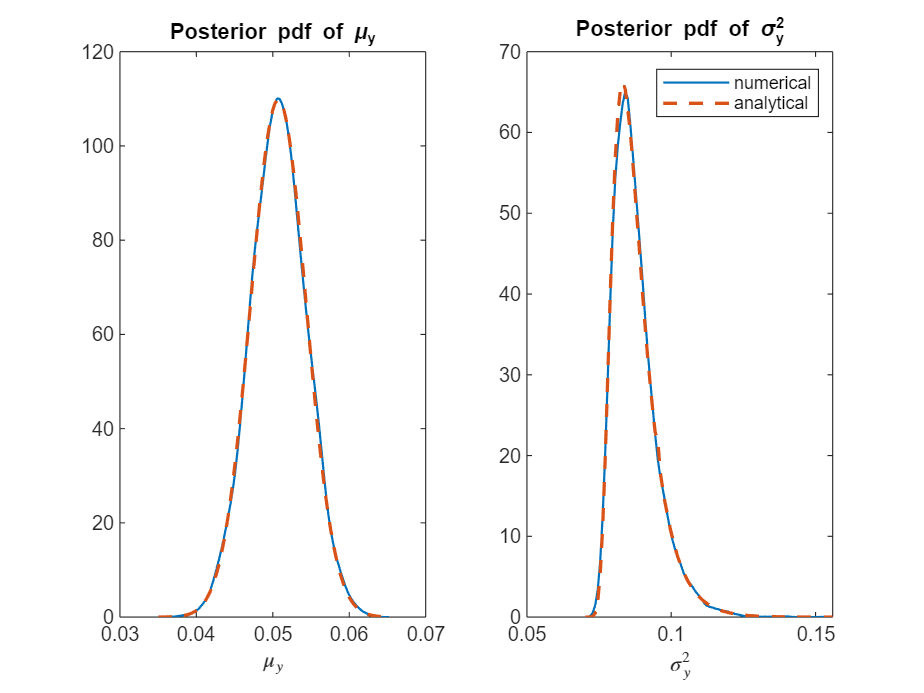

% compare numerical vs analytical posterior distribution
figure(2)
subplot(1,2,1)
plot(xi_mu_y,pdf_mu_y.pdf(xi_mu_y),'--','Color',RED,'LineWidth',1.5,'DisplayName','analytical');

subplot(1,2,2)
plot(xi_sig2_y,pdf_sig2_y.pdf(xi_sig2_y),'--','Color',RED,'LineWidth',1.5,'DisplayName','analytical');